# kgme

## load data structure

IN LAB

load("/Volumes/Elements/kg.mat");
addpath('/Users/eric/SparkleShare/github.com/FishCodeGH/Gallman/');

AT HOME

load("/Users/kathryngallman/Documents/MATLAB/kgtest2.mat");
addpath("/Users/kathryngallman/SparkleShare/github.com/FishCodeGH/Gallman");

## save data structure

IN LAB

save("/Users/eric/Documents/MATLAB/kgtest2.mat", "kg");
save("/Volumes/Elements/kg.mat", 'kg');

AT HOME

save("/Users/kathryngallman/Documents/MATLAB/kgtest2.mat", "kg");
save("/Volumes/Elements/kg.mat", 'kg');

## reference raw data folder and asign k value

%raw data files live on the MyBook. Thankfully... ugh.
cd("/Volumes/My Book/Gallman/1212LD/Paco12-Oct-20-2021-E/");

k = 67;

k = 1,2;           4:4 LD

k = 3-5;           48:48 LD 

k = 6, 7;          10:10 LD

k = 8, 9           6:6 LD

      k = 9 - time shifty

k = 10, 11;       24:24 LD

k = 12-17;       12:12 LD

    k=13 - two different fish (pepper then potts) - need to separate

    k = 15 very short and shitty

k = 18-20         5:5 LD

    k = 18 - shit data. replaced Eigen05-Nov-8-2020-A with new poweridx from k = 19;

    k = 20 - just weird. don't use light timers they shift

k = 21 - Eugene 

k = 22   Eugene 12:12 LD - wrong folder label - from super old data - spring 2020 Eigen

k = 23 - Milo

k = 24 - fish run - not sure which fish - need to check

k = 25-27         8:8 LD

k = 28-31        13:13 LD

    k = 29 - don't use. data is weird

    k = 30 - if trimmed and then outlier removed could salvage data - needs multiple power idxs

    k = 31 - needs second poweridx for channel 1 data - not sure about numberings yet

k = 32-34        6:6 LD

    k = 34 - weird data. backwards

k = 35, 36       8:8 LD

k = 37-40        20:20 LD

    k = 39 - salvagable, needs to be trimmed and outliered.  

k = 41-43        16:16 LD - kinda shitty tbh

k = 44-49         48:48 LD

    k = 45, 49 just not good

k = 50

k = 64-67        12:12 - 4:4 - 12:12 - 4:4 - 12:12 LD phase exp.

kg(k).e = KatieAssembler('Eigen*', 40000, 23);
%kg(k).e = KatieAssembler('Eigen*', 20000, 22); %really old data
%kg(k).e = KatieAssembler('Eigen*', 40000, 24); %Katie is bad at typing...

## initial plotter

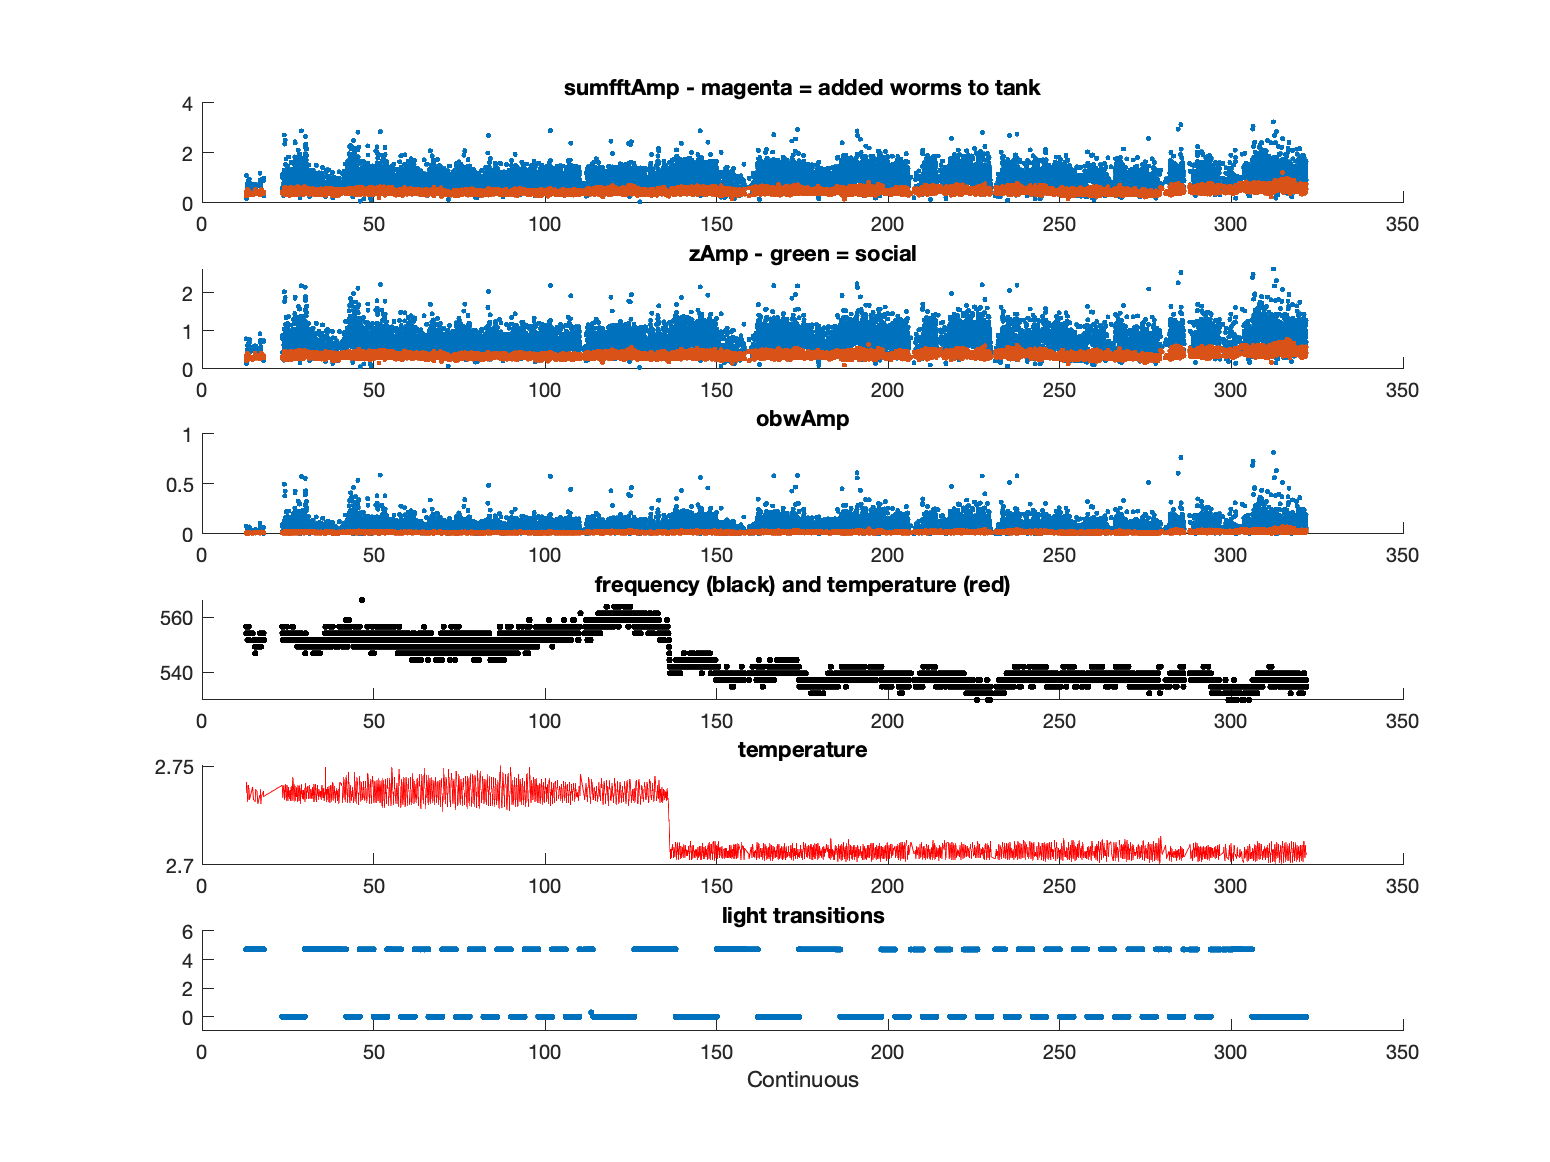

k_initialplotter(kg(k));

## edits

#### trim data

extra step in case of instant clicking regret...

tempdata = KatieTrimmer(kg(k).e);

if before was on purpose 

kg(k).e = tempdata;

#### Remove outliers

Must be redone after trimming

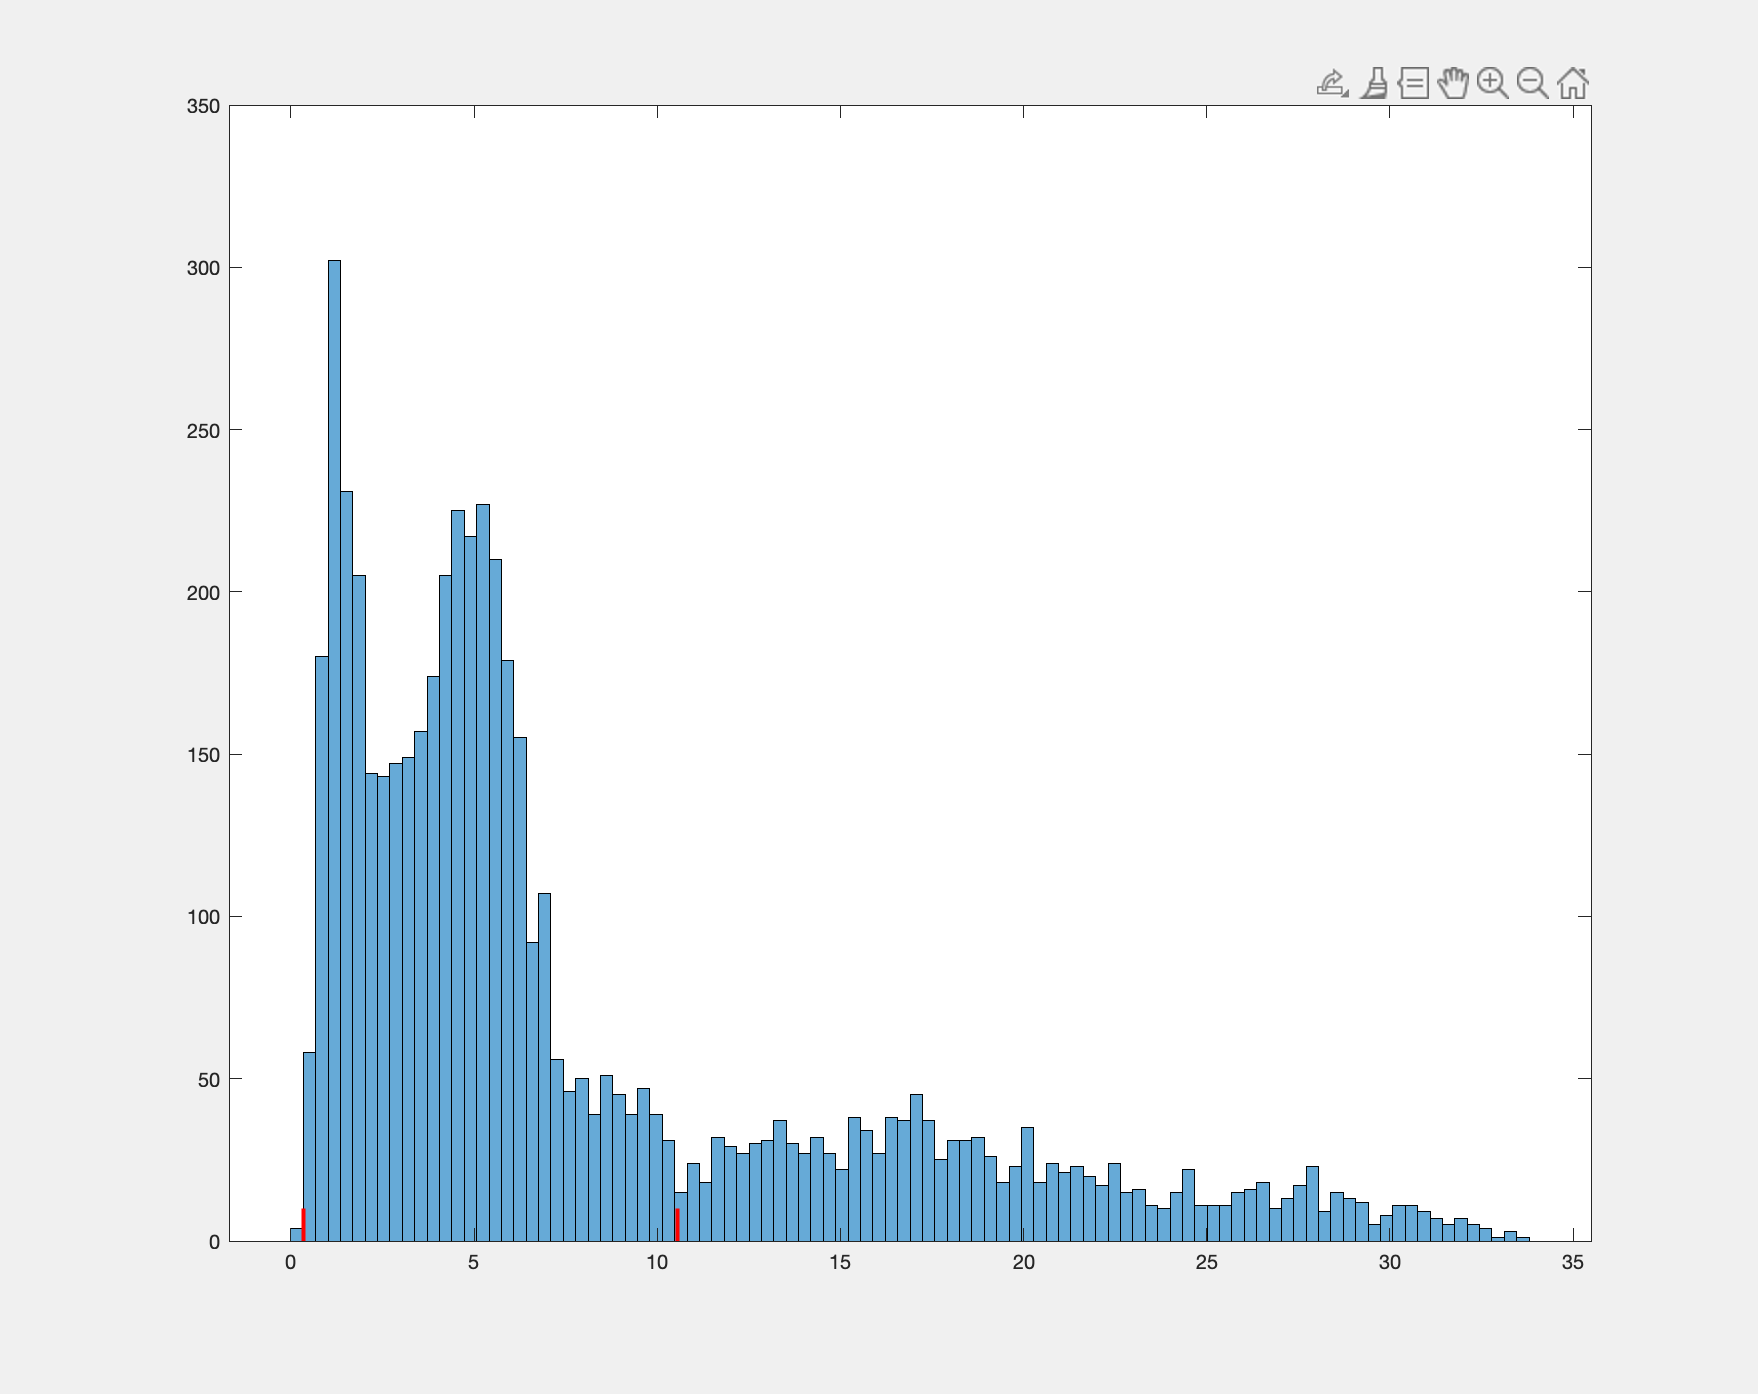

kg(k).idx = KatieRemover(kg(k).e);

## Label

#### light experiment

manual entry into command line - click in window 

kg(k).info = KatieLabeler(kg(k).e);

#### temperature experiment

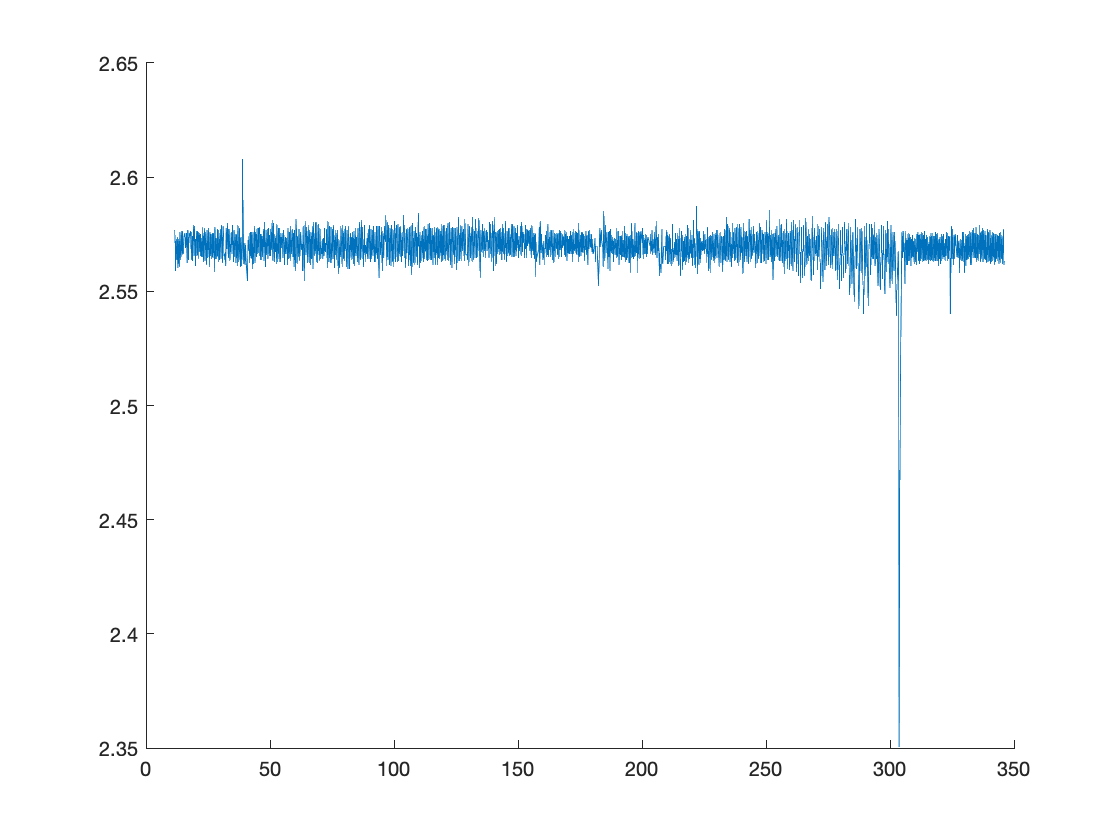

kg(k).info = KatieTempLabeler(kg(k).e);

## initial plotter

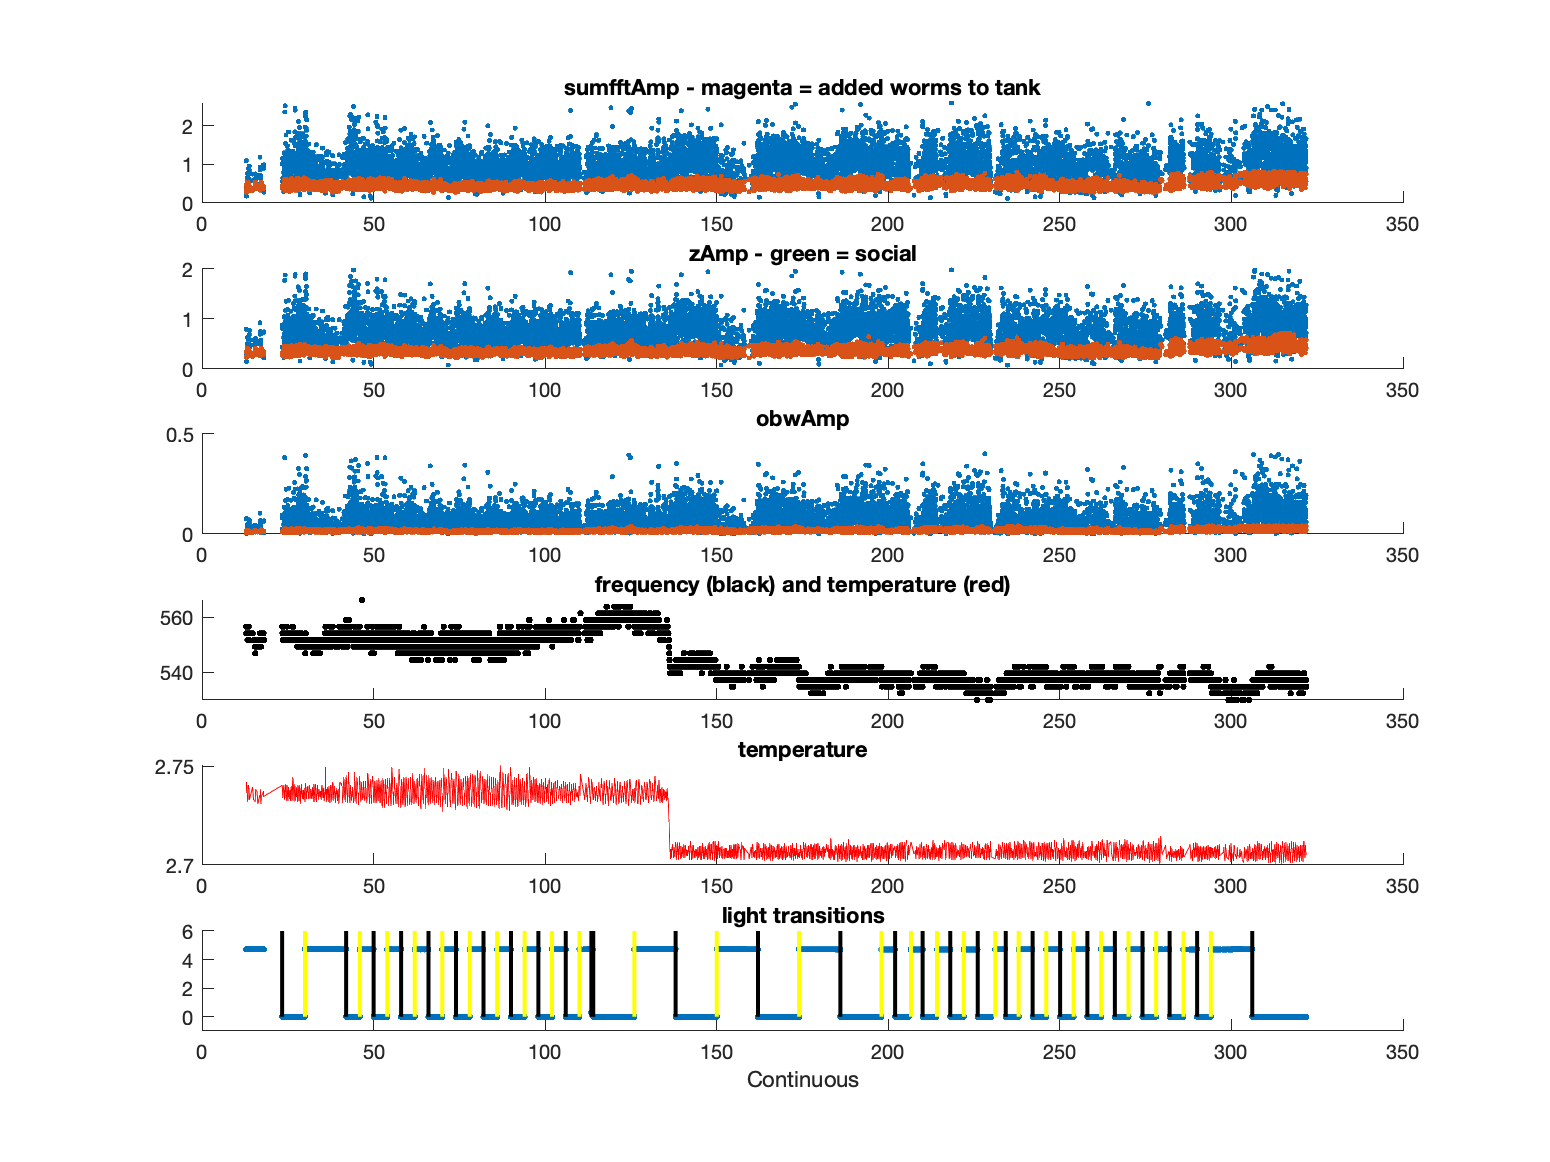

k_initialplotter(kg(k));